clear all
%Assign parameters
SIR_num = [9990,10,0]';%population distribution
population = sum(SIR_num);
SIR_initial = SIR_num / population;

deltaT = 0.01;%time step
tTotal = 36500;%total modelling time
beta = 0.1507;%infection rate
sigma = 0.063;%revovery rate
mu = 0.027;%death due to disease
omega = 0.0005;%loss of immunity
lambda = 0;%birth rate
ds = 0;%natrual death
di = 0;%natural death
dr = 0;%natural death

colorCode = ["#EDB120", "#FF0000", "#0000FF"];

%Predict using forward Euler
t(1) = 0; %start with 0 day
SIR_FE(:,1) = SIR_initial;
n = 1;

while t(n)<= tTotal
    SIR_FE(:,n+1) = SIR_Euler(deltaT,SIR_FE(:,n),lambda,beta,sigma,omega,mu,ds,di,dr);
    t(n+1) = t(n) + deltaT;
    n = n + 1;
end


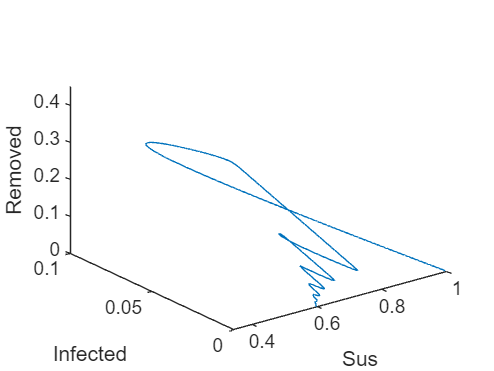

%Plot forward Eular
sizeSIR = size(SIR_FE);
numVar = sizeSIR(1);
legendName = ['Suspectible','infected','Removed'];
for i  = 1:numVar
    hold on
    plot(t/365,SIR_FE(i,:)*population)
end
xlabel('Year')

%Predict using RK4
t(1) = 0; %start with 0 day
SIR_RK(:,1) = SIR_initial;
n = 1;

while t(n)<= tTotal
    SIR_RK(:,n+1) = SIR_RK4(deltaT,SIR_RK(:,n),lambda,beta,sigma,omega,mu,ds,di,dr);
    t(n+1) = t(n) + deltaT;
    n = n + 1;
end

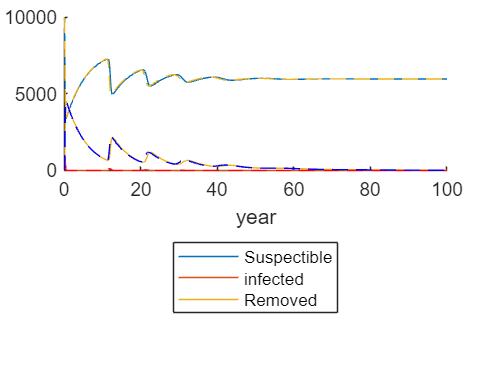

%Plot RK4
sizeSIR = size(SIR_RK);
numVar = sizeSIR(1);
legendName = ['Suspectible','infected','Removed'];
for i  = 1:numVar
    hold on
    plot(t/365,SIR_RK(i,:)*population,'--',Color=colorCode(i))
end
hold off
xlabel('year')
legend('Suspectible','infected','Removed',Location='southoutside')

plot3(SIR_RK(1,:),SIR_RK(2,:),SIR_RK(3,:))
xlabel('Sus')
ylabel('Infected')
zlabel('Removed')
  